n_1 = 3;
A = [[1e-1 2e-2 3e-2];
    [4e-2 5e-1 6e-2];
    [7e-2 8e-2 9e-1]];
b_1 = ones(n_1,1);
epsilon_1 = 1e-12;
x_1_si = SimpleIteration(A,b_1,epsilon_1);

Simple iterations:
Number of iterations:
    23



x_1_z = Seidel(A,b_1,epsilon_1);

Seidel:
Number of iterations:
    10




x_1_si

x_1_si =    9.685534591195079
   1.194968553459179
   0.251572327044079



x_1_z

x_1_z =    9.685534591194822
   1.194968553459136
   0.251572327044035


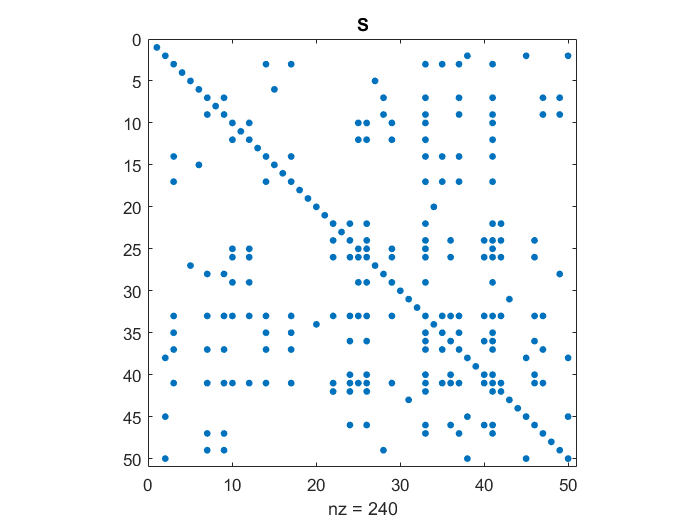


n  = 50;
R = rand(n, 1, 'double');
%S = sprandsym(n, 0.1, R);
spy(S), title('S');

epsilon_2 = 1e-12;
b_2 = ones(n, 1);

x_2_si = SimpleIteration(S, b_2, epsilon_2);

Simple iterations:
Number of iterations:
    59



x_2_z = Seidel(S, b_2, epsilon_2);

Seidel:
Number of iterations:
    30




x_2_si

x_2_si =    1.456080039292949
   3.703193010916486
   2.089936838591074
   1.598418050183245
   0.565943901284587
  -0.360645954918527
   2.854218461499895
   1.289137109108440
   1.538633269440063
   2.188697443649172



x_2_z

x_2_z =    1.456080039292949
   3.703193010916477
   2.089936838591074
   1.598418050183245
   0.565943901284587
  -0.360645954918527
   2.854218461499895
   1.289137109108440
   1.538633269440063
   2.188697443649172



n_2 = 10;
H = hilb(n_2);
e = ones(n_2, 1);
b_3 = H*e;
epsilon_3 = 1e-12;
x_3_si = SimpleIteration(H,b_3,epsilon_3);

Simple iterations:
Error: H matrix spectral radius is grater than 1


x_3_z = Seidel(H,b_3,epsilon_3);

Seidel:
Number of iterations:
   110650754




x_3_z

x_3_z =    0.999999998680313
   1.000000175783272
   0.999996278600748
   1.000028372475962
   0.999901302933946
   1.000160165475914
   0.999921787480158
   0.999902138893984
   1.000138114990737
   0.999951656879940


norm(x_3_z-e)

ans =      2.707762358152532e-04
